**Dear Students, **

**You are expected to submit the solved notebook by 6th Sepember 2022 (Tuesday), 11.59pm. **

# **Continuous-Time & Discrete-Time Sinusoids **

**Learning Outcome**: At the end of this exercise, you will be able to find out the differences between the continuous-time and discrete-time sinusoids. 

## Continuous-Time Sinusoids

The continuous-time sinusoid is given by

                                                                           
$$x(t) = \sin(\Omega t+\phi), \;\; t\in \mathbb{R}$$
 

Here, $t$ is the independent variable and $\Omega$ (radians/second) and $\phi$(radians) are the parameters, respectively, referred to as the frequency and phase of the continuous-time sinusoid. Note that $\Omega =2\pi \;F$, where $F$ is the frequency in $\textrm{Hz}\ldotp \;$

Now, construct and plot a continuous-time sinusoid. 

### **Coding :                                                                   **

Question 1: Construct and plot a continuous-time sinusoid when $\Omega =\;\Omega_0 =\frac{\pi }{6}$ radians/second and ${\phi =\phi }_0 =0$ radians (plot $5$ cycles). 

#### **Initialization:                                                                                                                                  **

% Choose appropriate numerical values for the below variable to emulate continuous-time in the digital computer
step = 1/12    % EXERCISE - Resolution of time variable

step = 0.0833

nCycles = 5 % EXERCISE - Number of cycles required

nCycles = 5

Omega = pi/6;  % EXERCISE - Radian frequency

phi = pi/2;    % EXERCISE - Phase
 period = 12  % EXERCISE - Compute the period of the sinusoid

period = 12

t = 0: step: 100 % EXERCISE - Fill in the blank to plot 4 cycles of the sinusoid.

t =          0    0.0833    0.1667    0.2500    0.3333    0.4167    0.5000    0.5833    0.6667    0.7500    0.8333    0.9167    1.0000    1.0833    1.1667    1.2500    1.3333    1.4167    1.5000    1.5833    1.6667    1.7500    1.8333    1.9167    2.0000    2.0833    2.1667    2.2500    2.3333    2.4167    2.5000    2.5833    2.6667    2.7500    2.8333    2.9167    3.0000    3.0833    3.1667    3.2500    3.3333    3.4167    3.5000    3.5833    3.6667    3.7500    3.8333    3.9167    4.0000    4.0833


sinusoidCT =  zeros(1,[]); % EXERCISE - this is x(t). Initialize it to zero, for each value of "t"

#### **Construction: **

sinusoidCT = sin(Omega*t+phi) ; % EXERCISE - construct continuous-time sinusoid. 

#### **Plotting:**

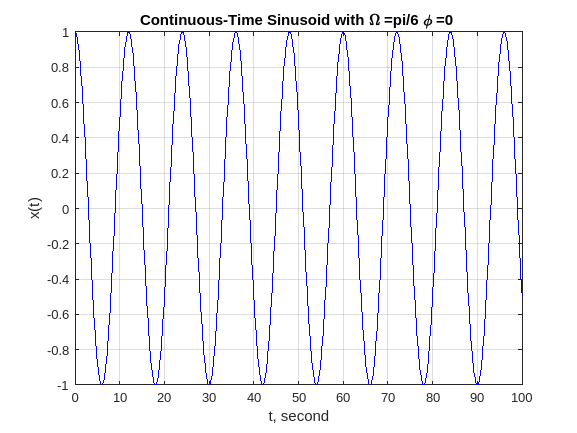

plot(t, sinusoidCT, 'b') 
title('Continuous-Time Sinusoid with \Omega =pi/6 \phi =0 ')
xlabel('t, second')
ylabel('x(t)')
grid


sound(sinusoidCT,50000)

### **Inferences :   **

Now, play with the above constructed continuous-time sinusoid, make observations and write down your inference. 

- Is the constructed signal Periodic or Aperiodic. comment how and why?

             ANSWER:    it is periodic , since it is repeating itself after interval of  t=12 which is its period 

- What is the relation between Phase ($\Omega$) and Periodicity. Hint: Change the Phase ($\Omega$) and observe the plot?

              ANSWER: 

- What is the relation between Phase ($\Omega$) and the Oscillations. Hint: Change the Phase ($\Omega$) and observe the plot?

              ANSWER: 

- What is the significance of "step" in the following code above?

              ANSWER: 

## **Practical Experiment :**

Now, construct and plot a continuous-time sinusoid when $\Omega =\;\Omega_0 =\frac{\pi }{4}$ radians/second and ${\phi =\phi }_0 =0$ radians. 

                      % Enter your code here
step = 1/8    % EXERCISE - Resolution of time variable

step = 0.1250

nCycles = 5 % EXERCISE - Number of cycles required

nCycles = 5

Omega = pi/4;  % EXERCISE - Radian frequency

phi = 0;    % EXERCISE - Phase
period = 8  % EXERCISE - Compute the period of the sinusoid

period = 8

t = 0: step: 100 % EXERCISE - Fill in the blank to plot 4 cycles of the sinusoid.

t =          0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750    1.0000    1.1250    1.2500    1.3750    1.5000    1.6250    1.7500    1.8750    2.0000    2.1250    2.2500    2.3750    2.5000    2.6250    2.7500    2.8750    3.0000    3.1250    3.2500    3.3750    3.5000    3.6250    3.7500    3.8750    4.0000    4.1250    4.2500    4.3750    4.5000    4.6250    4.7500    4.8750    5.0000    5.1250    5.2500    5.3750    5.5000    5.6250    5.7500    5.8750    6.0000    6.1250


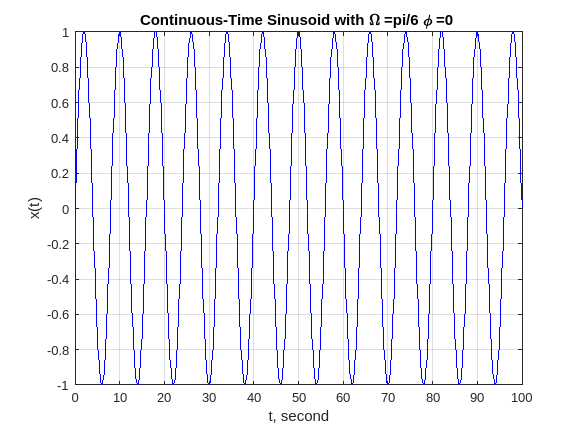

sinusoidCT =  zeros(1,[]); % EXERCISE - this is x(t). Initialize it to zero, for each value of "t"
sinusoidCT = sin(Omega*t+phi) ; % EXERCISE - construct continuous-time sinusoid. 
plot(t, sinusoidCT, 'b') 
title('Continuous-Time Sinusoid with \Omega =pi/6 \phi =0 ')
xlabel('t, second')
ylabel('x(t)')
grid

Write code to listen to the above generated signal. Note that you will need to associate your variable "t" with the physical time to listen the true signal of frequency $\Omega$. (see [sound](https://in.mathworks.com/help/matlab/ref/sound.html))

                       % Find out a function from Matlab to play a vector. 
sound(sinusoidCT,20000)                       

- What sampling frequency did you use in the above code? Why? 

              ANSWER: 

- Change the sampling frequency while playing the sound and listen to the sound. What happens when you increases and decrease the sampling frequency? 

              ANSWER: 

## Discrete-Time Sinusoids

Let's considere a continuous-time sinusoid with the sampling frequency, $F_s \ge 2F$. Let us select, $F_s =\;\;2$ Hz implying that $T_s =0\ldotp 5$second. 

In this case, we are going to take samples of $x\left(t\right)$ at  $t=0T_{s\;} ,1T_s ,2T_s$and so on and we will get the following sequence: $\left\lbrace x\left\lbrack 0\right\rbrack \;=\;x\left(0T_s \right),\;x\left\lbrack 1\right\rbrack \;=\;x\left(1T_s \right),\;x\left\lbrack 2\right\rbrack \;=\;x\left(2T_s \right),\ldots\right\rbrace \ldotp \;$

Compactly, this can be denoted as 

                                                                $x\left\lbrack n\right\rbrack =\;\cos \left(\Omega \;T_{s\;} n+\phi \right)\;=\;\cos \left(\omega \;n+\phi \right),\;\;\;\;n\in Z$, 

where  $\omega =\Omega \;T_s$ with radians/sample as the unit. We refer to $\omega$ as the discrete-time frequency, due to its similarity to the continuous-time frequency  Note that $\omega =2\pi \;f$, where the unit of$f$ is $\;\left(\textrm{ENTER}\;\textrm{YOUR}\;\textrm{EQUATION}\;\textrm{HERE}\right)\ldotp$ 

### **Coding :    **

Question 2: Construct and plot a discrete-time sinusoid when $\omega =\omega_0 =\Omega \;T_s$ radians/sample and ${\phi =\phi }_0 =0$ radians

#### **Initialization:                                                                                                                                  **


samplingPeriod =  1; %EXERCISE: Sampling period
nSamples = 1; %EXERCISE: Number of samples in 4 cycles of the continuous-time wave, in the first case. 
n = 0: 1/samplingPeriod: 100; % EXERCISE: Independent variable for the discrete-time sinusoid
Omega= 2*pi

Omega = 6.2832

omega = Omega * samplingPeriod; % EXERCISE: Discrete-time frequency from the continuous-time frequency
phi=0

phi = 0

sinusoidDT = zeros(1,[]); % EXERCISE - this is x[n]. Intialize it to zero, for each value of "n"


#### **Construction: **

sinusoidDT =  cos(omega*n+phi);  % EXERCISE - construct discrete-time sinusoid. 

#### **Plotting:**

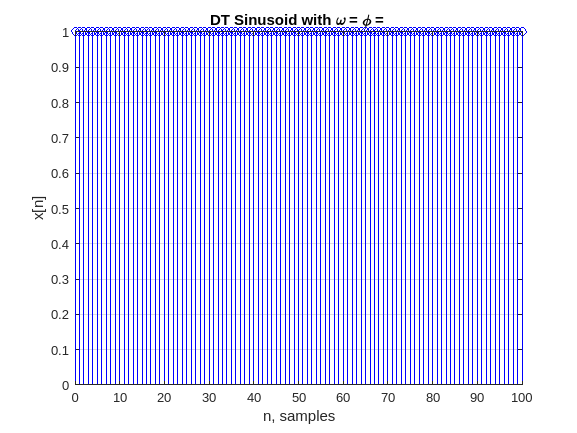

stem(n, sinusoidDT, 'b')
title('DT Sinusoid with \omega = \phi = ')
xlabel('n, samples')
ylabel('x[n]')
grid


sound(sinusoidDT,50000)

### **Inferences :   **

 Now, play with the above constructed discrete-time sinusoid, make observations and write down your inference. 

- Comment on the periodicity of $x\left\lbrack n\right\rbrack$ ? 

              ANSWER: 

- Let $x_1 \left\lbrack n\right\rbrack =\;\cos \left(\omega_{0\;} n+\phi \right)$ 

                   
$$x_2 \left\lbrack n\right\rbrack =\;\cos \left(\left(w_0 +2\pi \right)n+\phi \right)$$
 

                    Compare the two signal and comment on the result?

              ANSWER: 

- Now vary $\omega$, do you think that for every $\omega$, the sequence $x\left\lbrack n\right\rbrack$is periodic? If not, write down the condition on $\omega$ for $x\left\lbrack n\right\rbrack \;$to be periodic

                                                                 
$$\textrm{ENTER}\;\textrm{YOUR}\;\textrm{EQUATION}\;\textrm{HERE}$$


- Now vary $\omega$ $0\;\textrm{to}\;2\pi$. What happens to the rate of oscillation of $x\left\lbrack n\right\rbrack$when $\omega$ is varied from $0\;\textrm{to}\;\pi$ and $\pi \;\textrm{to}\;2\pi$?  

              ANSWER: 

### CONCLUSIONS :

- What are the key differences between continuous-time and discrete-time sinusoids. 

              ANSWER: 

# **Continuous-Time & Discrete-Time Sawtooth and Square Signals**

## Continuous-Time and Discrete-Time Square Signal

### **Coding :                                                                   **

Question 1: Construct and plot a continuous-time square signal of a frequency and duty cycle of your choice. 

% WRITE YOUR CODE HERE
fs = 100;
t = 0:1/fs:1;
squ=square(2*pi*5*t)

squ =      1     1     1     1     1     1     1     1     1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1     1     1     1     1     1     1     1     1     1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1     1     1     1     1     1     1     1     1     1     1


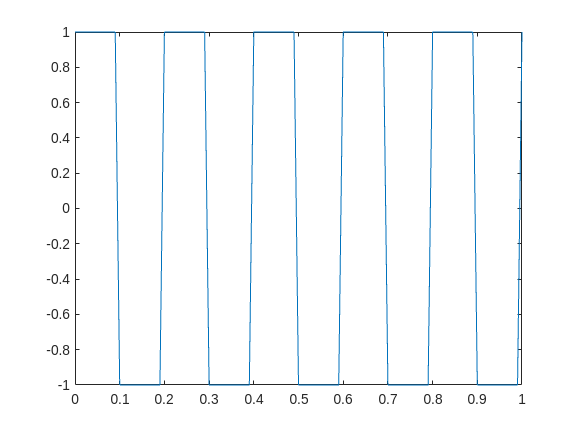

plot(t,squ)

Question 2: Now, sample the above signal with appropriate sampling frequency and plot the sequence.

% WRITE YOUR CODE HERE
fs = 50; % sampling 
t = 0:1/fs:1;
squ=square(2*pi*5*t)

squ =      1     1     1     1     1    -1    -1    -1    -1    -1     1     1     1     1     1    -1    -1    -1    -1    -1     1     1     1     1     1    -1    -1    -1    -1    -1     1     1     1     1     1    -1    -1    -1    -1    -1     1     1     1     1     1    -1    -1    -1    -1    -1


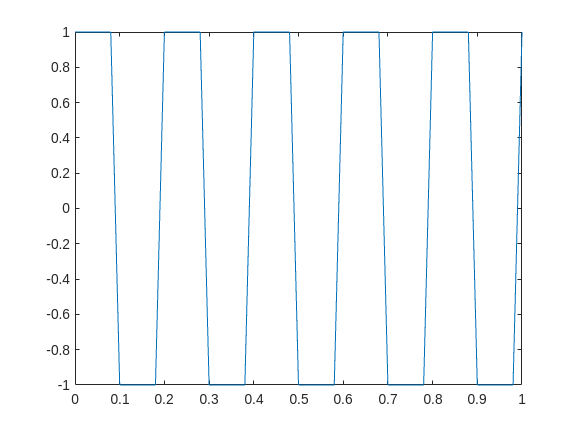

plot(t,squ)

### Inference :

What are your observations?

  ANSWER: 

Can you write the mathematical expression of the above plot?

ANSWER:

## Continuous-Time and Discrete-Time Triangular Signal

### **Coding :                                                                   **

Question 1: Construct and plot a continuous-time triangular signal of parameters of your choice. 

% WRITE YOUR CODE HERE
fs = 100;
t = 0:1/fs:1;
squ=sawtooth(2*pi*5*t)

squ =    -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


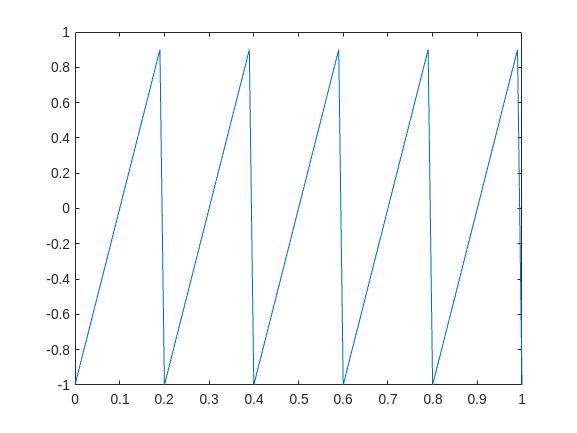

plot(t,squ)

Question 2: Now, sample the above signal with appropriate sampling frequency and plot the sequence.

% WRITE YOUR CODE HERE
fs = 50;
t = 0:1/fs:1;
squ=sawtooth(2*pi*5*t)

squ =    -1.0000   -0.8000   -0.6000   -0.4000   -0.2000         0    0.2000    0.4000    0.6000    0.8000   -1.0000   -0.8000   -0.6000   -0.4000   -0.2000         0    0.2000    0.4000    0.6000    0.8000   -1.0000   -0.8000   -0.6000   -0.4000   -0.2000         0    0.2000    0.4000    0.6000    0.8000   -1.0000   -0.8000   -0.6000   -0.4000   -0.2000         0    0.2000    0.4000    0.6000    0.8000   -1.0000   -0.8000   -0.6000   -0.4000   -0.2000         0    0.2000    0.4000    0.6000    0.8000


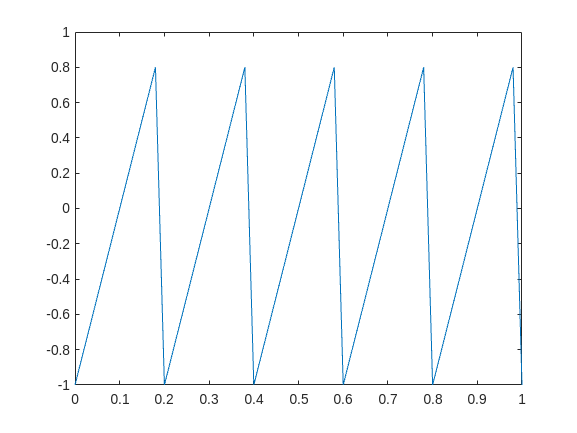

plot(t,squ)

### Inference **:     **

What are your observations?

  ANSWER: 

Can you write the mathematical expression of the above plot?

ANSWER:

# **Slow and Fast Convolutions  **

## **Learning Outcome**: 

At the end of this exercise, you will be able to implement the convolution operation to compute the output of a system given an input sequence and the impulse response of the system, using two different techniques. The technique we will explore are:

- Direct or Slow Convolution

- Fast Convolution 

## Background:

In the theory part, you studied about 4 ways of representing a linear time-invariant  (LTI) system. They are

- Impulse response, denoted by $h[n]$

- Frequency response, denoted by $H(e^{j\omega})$

- System function (Z-transform), denoted by $H(z
)$

- Linear Constant Coefficient Difference Equation, which is $y[n] = - \sum_{k=1}^Na_k y[n-k] + \sum_{k=0}^M b_kx[n-k]$. 

Each one of the above representations play a vital role in design and/or implementation of digital systems (such as filters). 

## Direct or Slow Convolution:

Given an input sequence, $x[n]$, of length $L_x$, we can compute the output sequence by the following convolution sum:  

                                                          $y[n] =  \sum_{k=0}^{L_h-1}h[k]x[n-k]$ for $n\in \mathbb{Z}$  

The above approach of computing convolution by direct evaluation of the convolution sum is called the Direct or Slow Convolution. The reason why it is called as the "Slow" convolution will be clear at the end.

### **Coding Question 1 : **

- Generate the impulse response, $h[n]$, of an arbitrary length, $L_h$. 

% Write your code here
%performing convolution of x(n) and h(n) 
%where h(n) is :
h=[0 1 2 3 0 0 0]

h =      0     1     2     3     0     0     0


n=[-2 -1 0 1 2 3 4]

n =     -2    -1     0     1     2     3     4


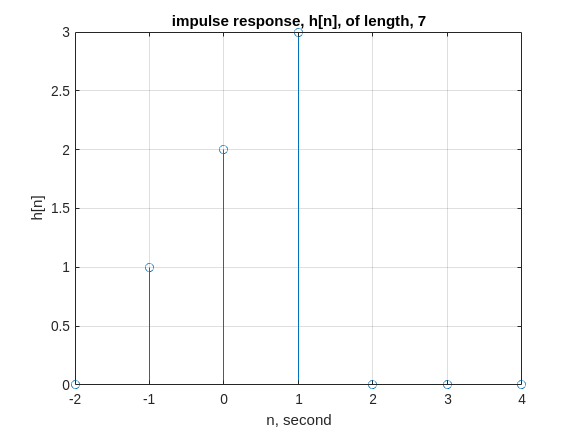

stem(n,h)
title('impulse response, h[n], of length, 7')
xlabel('n, second')
ylabel('h[n]')
grid

- Generate a discrete-time sequence, $x[n]$ of an arbitrary length, $L_x$. 

% Write your code here
x=[0 0 0 1 1 1 0]

x =      0     0     0     1     1     1     0


n=[-2 -1 0 1 2 3 4]

n =     -2    -1     0     1     2     3     4


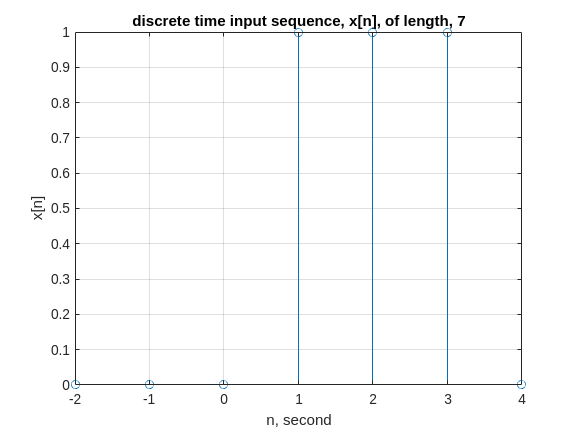

stem(n,x)
title('discrete time input sequence, x[n], of length, 7')
xlabel('n, second')
ylabel('x[n]')
grid

- Compute $y[n] = h[n]\ast x[n]$by evaluating the convolution sum. 

% Write your code here
z=[];   %for storing convolution matrix 
for i=1:length(x)
    g=h.*x(i);
    z=[z;g];
end
%performing convolution sum of matrix 
[r c]=size(z);
k=r+c;
t=2;
y=[];    %for storing computed convolution of matrix 
cd=0;
while(t<k)
    for i=1:r
        for j=1:c
            if((i+j)==t)
                cd=cd+z(i,j);
            end
        end
    end
   t=t+1;
   y=[y cd];
   cd=0;
end
disp(y);     %displaying y[n]

     0     0     0     0     1     3     6     5     3     0     0     0



ny=0:length(y)-1    %length of convolution sum

ny =      0     1     2     3     4     5     6     7     8     9    10    11


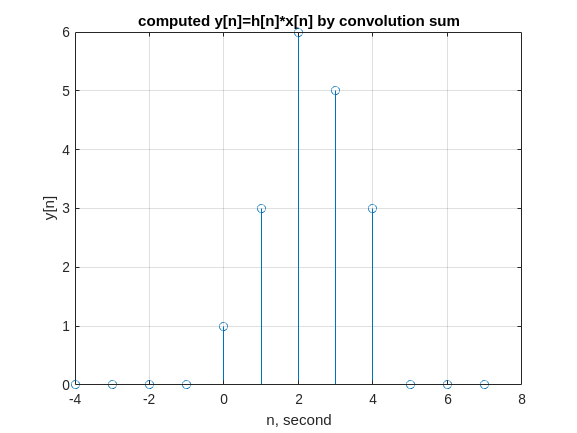

stem((ny-4),y)
title('computed y[n]=h[n]*x[n] by convolution sum')
xlabel('n, second')
ylabel('y[n]')
grid

- Verify your answer using the inbuilt Matlab function, [conv](https://in.mathworks.com/help/matlab/ref/conv.html). 

%Write your code here
y=conv(x,h)

y =      0     0     0     0     1     3     6     5     3     0     0     0     0


ny=0:length(y)-1

ny =      0     1     2     3     4     5     6     7     8     9    10    11    12


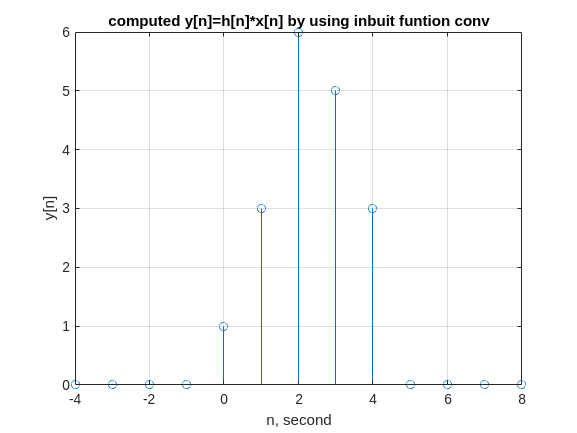

stem((ny-4),y)
title('computed y[n]=h[n]*x[n] by using inbuit funtion conv')
xlabel('n, second')
ylabel('y[n]')
grid

### **Inference 1 : **

- What is the maximum length of $y[n]$? Express your answer in terms of $L_h~\text{and} ~L_x$.

            ANSWER:  length of y[n] is   length(x)+length(h)-1=Lh+Lx-1  in above example length(x)=length(h)=7 so length(y)=13

## **Fast Convolution: **

Noting that discrete-time Fourier transform (DTFT) of $h[n]\ast x[n]$ is equal to $H(e^{j\omega})X(e^{j\omega})$, where $H(e^{j\omega}) = \text{DTFT}(h[n])$and $X(e^{j\omega}) = \text{DTFT}(X[n])$, we can consider the following approach for computing the convolution sum to obtain $y[n]$:

- Compute $H(e^{j\omega})$ and $X(e^{j\omega})$

- Obtain $Y(e^{j\omega})  =  H(e^{j\omega})X(e^{j\omega})$

- Compute the inverse DTFT of $Y(e^{j\omega})
$ to obtain $y[n]$. 

### **Coding Question 2 :**

- Compute and plot the DTFT of $h[n]$ you generated above, over $0\leq \omega <2\pi$.  

% WRITE YOUR CODE HERE. 

### **Coding Question 3 :**

- Write a code snipped to reconstruct $h[n]$ from the DTFT you have computed

% WRITE YOUR CODE HERE. 

### Inference 2 **:**

- Were you able to reconstruct $h[n]$ from $H(e^{j\omega})$? Why? Why not? 

            ANSWER:

- Which parameters in your code affect the reconstructability? 

            ANSWER:

As you might have noted, one of the main challenges with adopting the above approach is that computing the DTFT in a digital computer is not possible as $\omega
$ is a continuous variable representing the digital frequency.  One way to deal this problem is by using the approach you have just used!  That is, by computing DTFT values at closely (usually uniformly) spaced sample values of $\omega
$, i.e., at $-\pi, -\pi+\delta\omega, \pi+2\delta\omega, \ldots, \pi-\delta\omega, \pi$ or at $0,  \delta\omega, 2\delta\omega, \ldots, 2\pi-\delta\omega, 2\pi$ (Recall that it is sufficient to compute the DTFT function only over a period of length$2\pi$.)  However, we should be careful with this approach in that, we should select $\delta \omega$ such that we are able to reconstruct $x[n] $from the sampled DTFT.  Let us assume that $\delta \omega =  \frac{2\pi}{N}$, where, we need to select $N$ such that we are able to recover/reconstruct inverse DTFT values without loss of information. We will find such an $N$in the following. 

Assume a discrete-time sequence $x[n], -\infty<n<\infty$ and consider its DTFT  $X(e^{j\omega})$ at $\omega = \frac{2\pi}{N}k, \;\; k = 0,\ldots, N-1.$We have, 

                                                             $X\left(\frac{2\pi k}{N}\right) = \sum_{n=-\infty}^{\infty}x[n]e^{-j2\pi k n/N}},  k=1,\ldots, N-1.$ for $k=0,\ldots, N-1$.

Noting that $e^{-j2\pi k(n+mN)/N} = e^{-j2\pi kn/N} $for any integer $m$, we can re-arrange the above equation as follows:

                              
$$X\left(\frac{2\pi k}{N}\right) =\ldots+\sum_{n=-N}^{-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}
$$
  
$$+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}
$$
  
$$\sum_{n=N}^{2N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\ldots
$$
 
$$+\ldots
$$
  
$$=\sum_{l=-\infty}^{\infty} \sum_{n=l N}^{l N+N-1} x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}
$$


    Changing the index in the inner summation from $n $ to $n-lN$ and changing the order of the summation, we have, 

                                                                 $X\left(\frac{2\pi k}{N}\right) =\sum_{n=0}^{N-1}   \left[\sum_{l=-\infty}^{\infty} x[n-l N] \right]e^{-j2\pi k n/N}}$ for $k=0,\ldots, N-1.$

### **Coding Question 4 :**

- Compute and plot $4$-point DFT  of the sequence, $x[n] = [3, 1, 2, 1]$. Plot them in the same figure. 

- Compare your answer with the Matlab inbuilt function, [fft](https://in.mathworks.com/help/matlab/ref/fft.html)

            % Write your code here. 
N=4

N = 4

x=[3 1 2 1]

x =      3     1     2     1


%for padding zero when N>length(X)
L=length(x)

L = 4

if(N>L)
    for i=1:N-L
        x=[x zeros(1,N-L)];
    end
end
for k=0:N-1    %for k=0,1,  N-1
    for n=0:N-1   %for summation
        Wn=exp(-j*2*pi*k*n/N);
        X1(k+1,n+1)=Wn;
        
    end
end
Xk=X1*x';
k=0:N-1;
figure(1)
subplot(2,2,1)
stem(k,abs(Xk))
xlabel('k')
ylabel('|Xk|')
title('magnitude plot')
subplot(2,2,2)
stem(k,angle(Xk))
xlabel('k')
ylabel('angle Xk')
title('phase plot')

N=4

N = 4

p=[3 1 2 1]

p =      3     1     2     1


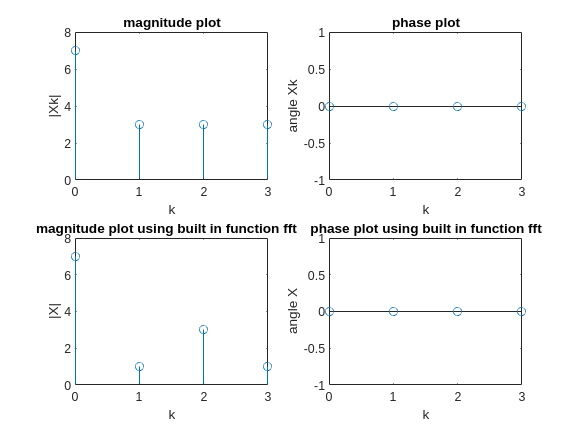

K=0:N-1;
F=fft(p,N);
figure(1)
subplot(2,2,3)
stem(K,abs(F))
xlabel('k')
ylabel('|X|')
title('magnitude plot using built in function fft   ')

subplot(2,2,4)
stem(K,angle(F))
xlabel('k')
ylabel('angle X')
title('phase plot using built in function fft')

- Now, plot the DTFT of $x[n]$ for $\omega\in [-\pi, \pi]$, based on your DFT coefficients. (see [fftshift](https://in.mathworks.com/help/matlab/ref/fftshift.html))

            % Write your code here. 
%plotting of DTFT of x(n)


### Inference 4 **:**

- What are your observations? 

Recall that we wanted to obtain the sequence $y[n]$. We have developed a way to compute a Fourier Transform and its inverse, namely DFT and IDFT of a discrete sequence in a digital computer. Now, can we compute DFTs of $h[n]$ and $x[n]$ to obtain $H[k]$ and $X[k]$, respectively, multiply them and take the IDFT of the result to get $y[n]? $

For answering the above question, recall the following from your Signals and Systems class:

Assume that  $H[k]$ and $X[k]$ are $M$-point DFT of $h[n]$ and $x[n]$, respectively. Then, 

                                                                  $\tilde{y}[n] = M\text{-Point IDFT}(X[k]H[k]) = \sum_{k=0}^{M-1}h[k][x[(n-k)_M]$, for $n = 0,\ldots, M-1$

where $(n-k)_M$ is the modulo $M$value of $(n-k)$which will take a value in $\{0,1, \ldots, M-1\}$. 

The above operation is called the circular *convolution *and it is usually denoted by $\otimes$, i.e., the $M$-point circular convolution of  $h[n]$ and $x[n]$,  $h[n]\otimes x[n] = \sum_{k=0}^{M-1}h[k][x[(n-k)_M]$. 

### Coding Question 5 **:**

- Generate $h[n]$ and $x[n]$ of lengths $L_h$ and $L_x$, respectively. 

- Compute $M$-point circular convolution of them. 

- Compute $H[k]$ and $X[k]$,  $M$-point DFTs of $h[n]$ and $x[n]$, respectively for an arbitrary value of $M$. 

% Write your code here. 
figure
N=4;
x=[0 1 0 1 ];
h=[1 2 1 2 ];
K=0:N-1;
xK=fft(x,N);    %X[k] of  x(n)
hK=fft(h,N);    %H[k] of  h(n)
XK=xK.*hK;
XK_n=cconv(x,h,4)

XK_n =      4     2     4     2


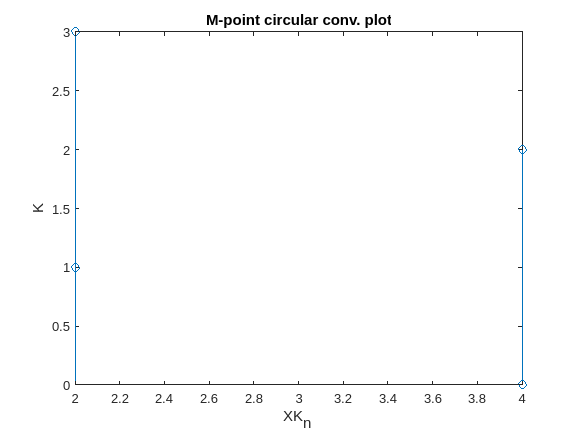

stem(XK_n,K)
xlabel('XK_n ')
ylabel('K')
title('M-point circular conv. plot')

Under the above condition on $M$, we can obtain the output $y[n]$using the above technique. Such a technique of obtaining the convolution sum of two finite-length sequences, using the DFT and IDFT operations is called as the *fast convolution. *You may be wondering why it would be fast, as it seems to involve more number of steps than with the *direct convolution * used earlier. However, it turns out that when the DFT and IDFT are computed using any of a large class of algorithms called Fast Fourier Transforms (FFT), fast convolution is more efficient (faster) than the direct convolution.  Hence, the fast convolution is a very important signal processing tool. Can you think of some advantages of direct convolution over the fast convolution? 

## Other References

- [https://allsignalprocessing.com/](https://allsignalprocessing.com/)

- John G. Proakis and D.G. Manolakis, Digital Signal Processing: Principles, Algorithms and Applications, Prentice Hall, Fourth Edition.

- L.R. Rabiner and B. Gold, Theory and Application of Digital Signal Processing, Prentice Hall, 1992. 

- A.V. Oppenheim and R. W. Schafer, Discrete-Time Signal Processing, Prentice Hall, 3rd Edition.